# **Level (2) Experiment Results**

In level 2 the purpose is to test how ChatGPT handles calling multiple tools after each other. 

go_to_area function is loaded with the following possibilities: 

`"Kitchen", "Office", "Bed Room", "Living Room", "Dining Room", "Workshop", "Garden", "Garage", "Home"`

locate_object function is loaded with the following possibilities:

"Banana", "Apple", "Cup", "Laptop", "Dog", "Cat", "Bottle", "Teddy Bear", "Person", "Bowl", "Refrigerator".

#### **Experimental setup:**

The online free version of ChatGPT has been used to generate 200 sentence example to call each of the avalible parameter options. The result has then been saved to a .csv file.

#### **Configuration:**

The best performing configuration for level 1 has been used in this test. 

#### **Test examples:**

?

function [successCount, failureCount, clarificationCount] = countStatus(filename, column)
    % Load the CSV file
    data = readtable(filename,'VariableNamingRule', 'preserve'); % Use readtable for more flexibility

    % Extract relevant column
    statusData = data.(column);

    % Initialize counters
    successCount = 0;
    failureCount = 0;
    clarificationCount = 0;

    % Iterate through each row
    for i = 1:height(data)
        % Check the value and increment the corresponding counter
        if strcmpi(statusData{i}, 'SUCCESS')
            successCount = successCount + 1;
        elseif strcmpi(statusData{i}, 'FAILURE')
            failureCount = failureCount + 1;
        elseif strcmpi(statusData{i}, 'CLARIFICATION')
            clarificationCount = clarificationCount + 1;
        end
    end
end

function plotStatusCounts(folderPath, column)
    % Get a list of all CSV files in the directory
    files = dir(fullfile(folderPath, '*.csv'));

    % Initialize variables to hold success, failure, and clarification counts for all files
    allCountSuccess = [];
    allCountFailure = [];
    allCountClarification = [];

    % Loop over each file in the folder
    for idx = 1:length(files)
        % Construct the full file path
        filename = fullfile(folderPath, files(idx).name);

        % Call your function to get counts for each experiment
        [countSuccess, countFailure, countClarification] = countStatus(filename, column);

        % Store the counts
        allCountSuccess(end + 1) = countSuccess;
        allCountFailure(end + 1) = countFailure;
        allCountClarification(end + 1) = countClarification;
    end

    % Define colors for the bars
    colorSuccess = [0, 1, 0]; % Green for success
    colorFailure = [1, 0, 0]; % Red for failure
    colorClarification = [0, 0, 1]; % Blue for clarification

    % Set the width of the bars here (between 0 and 1)
    barWidth = 0.4; % Adjust this as needed

    % X positions for each set of bars
    xPositions = 1:length(files); % Adjust according to the number of files

    % Create grouped bar graph
    fig = figure;
    b = bar(xPositions, [allCountSuccess; allCountClarification; allCountFailure]', barWidth, 'stacked');

    % Set the colors for success, clarification, and failure
    set(b(1), 'FaceColor', colorSuccess);
    set(b(2), 'FaceColor', colorClarification);
    set(b(3), 'FaceColor', colorFailure);

    % Add text labels for each count value
    for i = 1:length(xPositions)
        % Text for success count
        if b(1).YData(i) > 0
            successText = num2str(b(1).YData(i));
            text(i, b(1).YData(i)/2, successText, 'HorizontalAlignment', 'center', 'Color', 'black', 'FontWeight', 'bold');
        end

        % Text for clarification count
        if b(2).YData(i) > 0
            clarificationText = num2str(b(2).YData(i));
            text(i, b(1).YData(i) + b(2).YData(i)/2, clarificationText, 'HorizontalAlignment', 'center', 'Color', 'black', 'FontWeight', 'bold');
        end

        % Text for failure count, displayed above the success and clarification count
        if b(3).YData(i) > 0
            failureText = num2str(b(3).YData(i));
            text(i, b(1).YData(i) + b(2).YData(i) + b(3).YData(i)/2, failureText, 'HorizontalAlignment', 'center', 'Color', 'black', 'FontWeight', 'bold');
        end
    end

    % Add legend
    legend({'Success', 'Clarification', 'Failure'}, 'Location', 'NorthEast');

    % Set labels and title
    xlabel('Configuration');
    ylabel('Count');
    title('GPT3:Status Counts for different amount of tasks being called','FontSize', 28, 'FontWeight', 'Bold');

    % Set x-axis limits and ticks
    xlim([0.5, length(files) + 0.5]);
    xticks(xPositions);
    % Generate and set x-tick labels as "Config 1", "Config 2", etc.
    configLabels = arrayfun(@(x) sprintf('Number of tasks: %d', x), 2:length(files)+1, 'UniformOutput', false);
    xticklabels(configLabels);

    % Set figure size for saving
    set(fig, 'Units', 'Inches', 'Position', [0, 0, 7, 5], 'PaperUnits', 'Inches', 'PaperSize', [7, 5]);

    % Extract the folder name from the folder path for use in the title
    [~, folderName] = fileparts(folderPath);

    % Improve the font
    set(gca, 'FontName', 'Helvetica', 'FontSize', 20);
    title_text = 'GPT-3.5: Result for different number of level 1 tasks';
    title(title_text, 'FontSize', 28, 'FontWeight', 'Bold');

    % Add grid lines for better readability
    grid on;
    set(gca, 'GridLineStyle', '--', 'GridColor', 'k', 'GridAlpha', 0.2);

    % Remove the top and right axis lines
    box off;
end


## Main folder

level02_function_folder = '/home/rasmus/Desktop/Master/MasterThesisGit/final_tests/abstraction_tests/Test_results/GPT3/Sorted_for_matlab/Level02';
column_result = 'Results';

## Testing using only example from Level 0

Here it the function

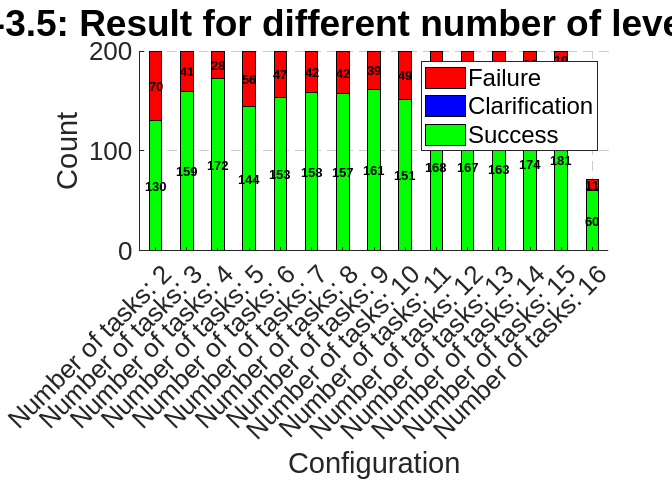

folderPath_level0 = fullfile(level02_function_folder,'level_0_only');

% We first needs the data
plotStatusCounts(folderPath_level0,column_result)

## Testing using only example from Level 1

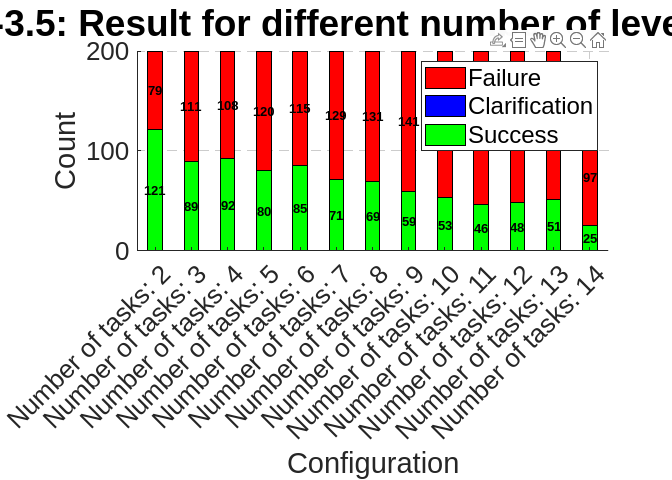

folderPath_level1 = fullfile(level02_function_folder,'level_1');
plotStatusCounts(folderPath_level1,column_result)